# Modelo SEIRS

**Universidad eafit**

**Segundo Semestre 2024**

**Sistemas lineales**

**Carlos M. Veléz S.**

**Luis M. Martinez G.**

**Sebastian A. Amaya C.**

## 1. El Modelo SIERS

El modelo SEIRS, una piedra angular de la epidemiología, divide las poblaciones en compartimentos susceptibles (S), expuestos (E), infecciosas (I), recuperadas (R) y nuevamente susceptibles (S), lo que proporciona un enfoque estructurado para estudiar la dinámica de transmisión de enfermedades. A través de ecuaciones diferenciales, rastrea el movimiento de los individuos entre estos compartimentos a lo largo del tiempo, lo que refleja las transiciones de la susceptibilidad a la exposición, la infección y, en última instancia, la recuperación o la susceptibilidad nuevamente.

La versatilidad de este modelo se extiende a diversas aplicaciones, incluida la predicción de la propagación de enfermedades, la evaluación de estrategias de intervención y la optimización de la asignación de recursos durante los brotes. Al simular diferentes escenarios, los investigadores y los responsables de la formulación de políticas pueden anticipar la trayectoria de las enfermedades infecciosas, evaluar la eficacia de las medidas de control y tomar decisiones informadas para mitigar su impacto en la salud pública.

Su marco matemático proporciona información sobre las tasas de transmisión, los períodos de latencia y la dinámica de la inmunidad, lo que permite a las partes interesadas implementar medidas proactivas y gestionar eficazmente los brotes de enfermedades dentro de las poblaciones.

### **1.1. DESCRIPCIÓN DEL MODELO**

La mayoría de las descripciones matemáticas de la dinámica poblacional de las enfermedades infecciosas se basan en la capacidad de dividir la población en compartimentos discretos que no se superponen para así estudiar el flujo de los individuos a través de las diferentes clasificaciones. Para este Modelo se estudian 4 compartimientos:

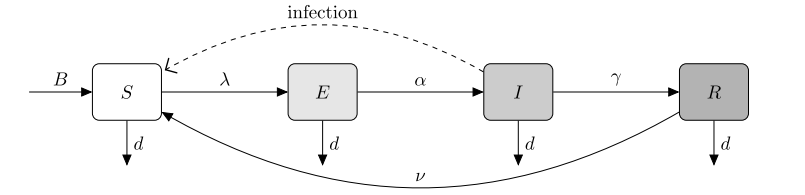

#### **Figura 1**

La figura 1 nos brinda un "esquema" del modelo y de la interacción de entre las poblaciones del modelo de esta práctica, es importante hacer clara ciertas consideraciones del modelo, primero, tomando una visión centrada en el patógeno, categorizamos al huésped (persona) por su estado con respecto al patógeno, Como las siglas del modelo indican los compartimientos en los que se divide la población son:

- Susceptibles(S):Individuos que no han sido infectados por la enfermedad y que pueden contraerla si entran en contacto con personas infectadas

- Infecciosas(I):Individuos actualmente infectados con la enfermedad y que pueden transmitirla a otros susceptibles.

- Recuperados(R):Individuos que han sido infectados previamente, pero ya se han recuperado de la enfermedad. Son inmunes y pueden volver a contraer la enfermedad.

- Expuestos(E): Individuos que han sido infectados con una enfermedad, pero que aún no son contagiosos.

- Población total (N): es la suma de todas las poblaciones anteriores

Además, podemos observar que se considera una población aislada y que la enfermedad modelada no es mortal, es decir la única entrada de nuevos integrantes es mediante nacimientos  y la única salida es mediante muerte por causas ajenas al patógeno, en la siguiente sección se explicara con mayor detalle la dinámica del modelo.

### **1.2. VARIABLES Y PARÁMETROS DEL MODELO**

Se puede observar que se usan varios parámetros para regular el flujo entre las diferentes poblaciones, a continuación se da una descripción de estas:

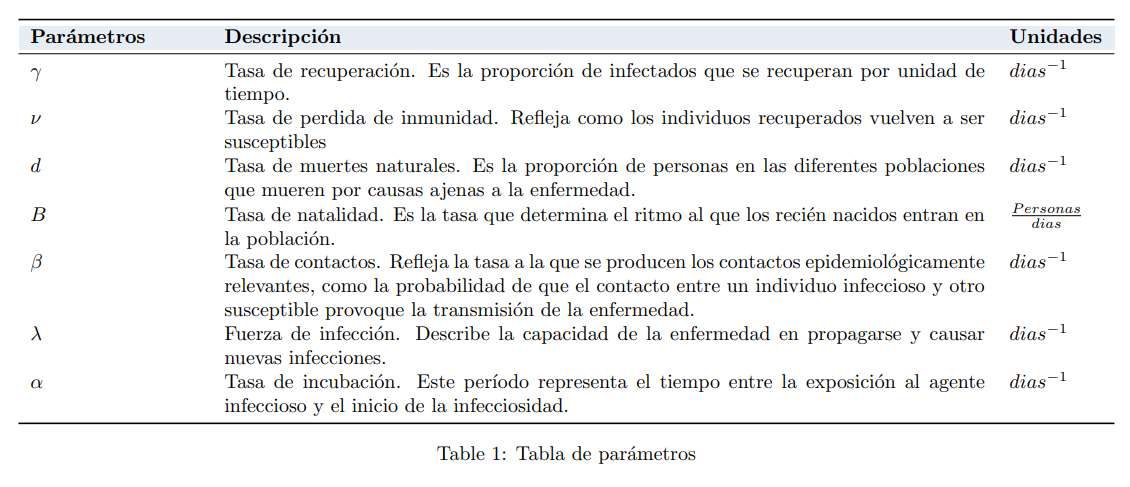

#### **Figura 2**

### **1.3 ECUACIONES DEL MODELO**

Considerando la clasificación de la población previamente establecida, las ecuaciones no lineales del modelo se pueden describir de la siguiente manera:

La población susceptible `(S)` varía con el tiempo `(t)`, aumentando con la llegada de recién nacidos `(B) `y los recuperados que pierden su inmunidad `(νR)`, y disminuyendo con los susceptibles que son infectados `(-λS)` y los que han muerto por causas naturales `(-dS)`.


$$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$$
  

La población expuesta `(E)` varía con el tiempo `(t)`, incrementando con los susceptibles que han sido infectados `(λS)` y disminuyendo con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(-αE)` y los expuestos que han fallecido por causas naturales `(-dE)`.


$$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$$
  

La población infectada `(I)` varía con el tiempo `(t)`, aumentando con los individuos expuestos que incuban la enfermedad (se vuelven infecciosos) `(αE)`, y reduciendo con aquellos infectados que se han recuperado `(-γI) `o han fallecido por causas naturales `(-dI)`.


$$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$$
 

La población recuperada `(R)` varía con el tiempo `(t)`, incrementando con los individuos infectados que se han recuperado `(γI)` y reduciendo con aquellos recuperados que pierden su inmunidad y se vuelven susceptibles de nuevo `(-νR)` y los recuperados que han fallecido por causas naturales `(-dR)`.


$$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$$


Debido a que el tamaño de nuestra población es variable, el valor de la fuerza de infección **(λ) **se actualiza constantemente


$$\lambda=\frac{\beta I}{N}$$


El modelo completo se compone de las siguientes 5 ecuaciones:

**(1) **$\frac{\mathrm{dS} }{\mathrm{d} t}=B+\nu R-\lambda S-dS$            

**(2) **$\frac{\mathrm{d} E}{\mathrm{d} t}=\lambda S -\alpha E-dE$                

**(3) **$\frac{\mathrm{d} I }{\mathrm{d} t}=\alpha E - \gamma I-dI$                 

**(4) **$\frac{\mathrm{d} R }{\mathrm{d} t}= \gamma I-\nu R-dR$                  

**(5) **$\lambda=\frac{\beta I}{N}$                                

### **1.4 HIPÓTESIS**

- Debido a la complejidad del sistema es posible que el modelo no sea controlable pero si observable 

- Debido a la complejidad del sistema es posible que se requiera el uso de varias variables de estado para cumplir la observabilidad

## 2. MÉTODOS

A continuacion se describe la metodologia usada para la verificacion del sistema, la implementacion de un filtro de kalman extendido, un filtro de kalman conjunto y un flitro de kalman junto a un control lineal

### 2.1 MODELO VERIFICADO DEL SISTEMA EN SIMULINK

Se Realiza la verificación del modelo al recrear la figura 3 de  [1] que representa el comportamiento del modelo SIERS, para cumplir este objetivo se realiza la simulación con parámetros que se enlistaran próximamente y se compara la simulación con la gráfica de referencia.

- ***β***=0.2

- `ν`=0.001

- ***α***=0.1

- `γ`=0.1

- `d`=0.0001

- `B`=0.0001

### **2.2 Discretización del modelo SEIR**

El modelo SEIR fue discretizado de forma analítica utilizando un paso de muestreo constante $Ts$. Esta discretización permitió obtener una representación en tiempo discreto, esencial para los análisis de observabilidad, control y la implementación de filtros de Kalman.

### **2.3 Cálculo de la matriz de transición **$\Phi$

La matriz de transición del sistema, $\Phi$, fue calculada como $\Phi = I + A \cdot Ts$, donde $I$ es la matriz identidad y $A$ es el jacobiano del modelo continuo, derivado analíticamente. Esta matriz es utilizada tanto para evaluar la observabilidad del sistema como para la implementación del filtro de Kalman extendido y el diseño de control.

### **2.4 Evaluación de la observabilidad**

La observabilidad del sistema fue evaluada considerando diferentes combinaciones de variables de estado del modelo SEIR. Este análisis permitió identificar las variables de estado que podían ser observadas directamente y aquellas que requerían ser estimadas. Las variables seleccionadas como observables se usaron para generar datos sintéticos, que sirvieron como entrada para los filtros de Kalman.

### 2.5 Generación de datos observables

Para las variables de estado identificadas como observables, se generaron datos sintéticos utilizando los parámetros con los que se verifico el codigo. Estos datos se utilizaron como entrada para los filtros de Kalman (se toman las variables que permiten la obsevabilidad) y permitieron evaluar la capacidad del modelo para capturar la dinámica del sistema real.

### **2.6 Implementación del filtro de Kalman extendido**

El filtro de Kalman extendido (EKF) se utilizó para estimar las variables de estado en el modelo SEIR. La implementación siguió los siguientes pasos:

- **Discretización del Modelo SEIR:**El modelo fue discretizado analíticamente usando un esquema explícito. La matriz de transición de estados $\Phi$ se calculó como:$\Phi = I + A \cdot Ts$,donde $A$ es el jacobiano de las ecuaciones del modelo, calculado de forma analítica.

- **Evaluación de la Observabilidad:**Se analizó la observabilidad del sistema considerando diferentes combinaciones de las variables de estado del modelo SEIR. Esto permitió identificar las variables que se pueden estimar de manera confiable.

- **Configuración del Filtro:**Se definieron las siguientes matrices para el filtro: 

- $Q$: Covarianza del ruido del proceso.

- $R$: Covarianza del ruido de medición.

- $P_0$: Covarianza inicial del error de estimación.

### **2.7 Filtro de Kalman conjunto para la estimación del parámetro **$\nu$

El filtro de Kalman conjunto se utilizó para estimar simultáneamente las variables de estado del modelo SEIR y el parámetro $\nu$. La implementación se desarrolló de manera analoga a la del filtro EKF, con la diferencia de que el sistema fue ampliado para incluir $\nu$ como una variable de estado adicional, permitiendo su estimación junto con las variables $S$, $E$, $I$ y $R$.

### **2.8 Control de realimentación del estado con un filtro de Kalman extendido**

Se diseñó un controlador de realimentación de estados utilizando un filtro de Kalman extendido como observador.

- **Linealización y Discretización del Modelo:**El modelo no lineal se linealizó alrededor de un punto de equilibrio definido por los valores iniciales de las variables de estado (usando la funcion linmod de matlab). A partir de esta linealización, se obtuvieron las matrices del sistema lineal. Luego, el sistema fue discretizado considerando un tiempo de muestreo constante (usando la funcion c2d de matlab).

- **Evaluación de la Controlabilidad:**Se evaluó la controlabilidad del sistema linealizado en su versión discreta mediante el cálculo de la matriz de controlabilidad (usando la funcion ctrb de mat;ab. El numero de condicion de esta matriz determinara  si el sistema es controlable o no. Independiente del caso se implementara el control para analizar los resultados.

- **Diseño del Controlador:**El diseño del controlador se realizó mediante la asignación de polos. A partir de esto, se calculó la ganancia del controlador usando la funcion place de matlab.

- **Integración con el Observador:**Las estimaciones de las variables de estado obtenidas mediante el filtro de Kalman extendido se utilizaron como entrada del controlador, permitiendo implementar un esquema en lazo cerrado.

## **3. Resultados**

### **3.1. VERIFICACIÓN DE CÓDIGO**

Dias=2500;
B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_

mdl = 'SEIRS_2';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
set_param(path, 'Ruido',0);
set_param(path,'Var_ruido',num2str(1e-8));

S0=1-1e-6;
E0=0;
I0=1e-6;
R0=0;
TS=1;
u=timetable(seconds(0),0);
simulacion_1_verificacion=sim("SEIRS_2.slx");
tiempo=simulacion_1_verificacion.tout;
infectados=simulacion_1_verificacion.I.signals.values;

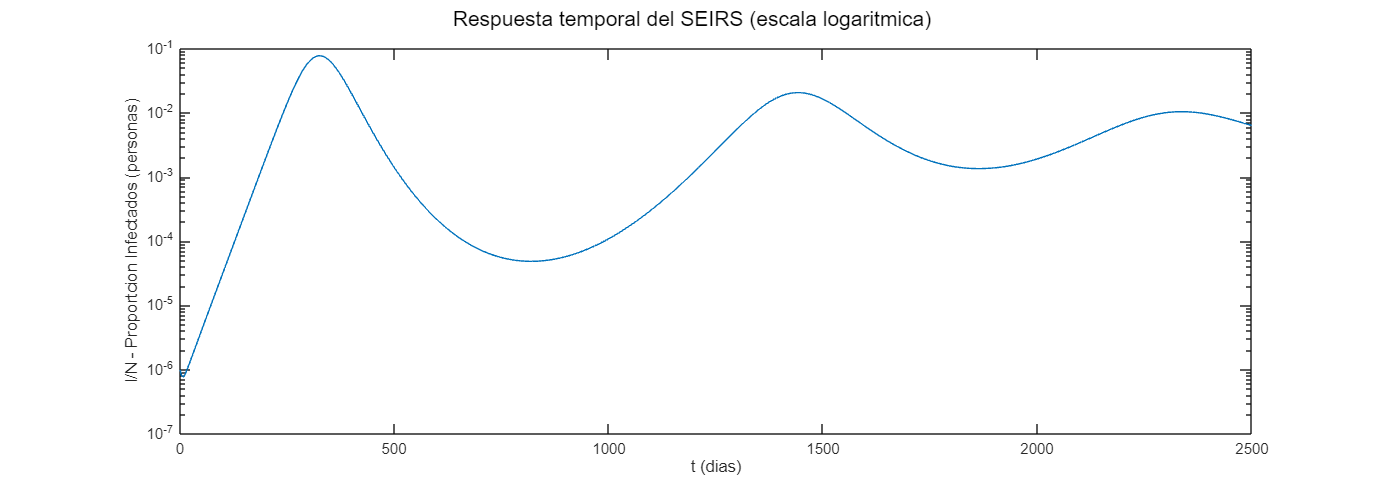


h1 = figure;
subplot(1,1,1), plot(tiempo,infectados), xlabel('t (dias)'), ylabel('I/N - Proportcion Infectados (personas)')
set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);
yscale log
sgtitle('Respuesta temporal del SEIRS (escala logaritmica)')

### 3.2 Modelo SEIR Discreto


$$\[
S(k+1) = S(k) + TS \left( B + \nu R(k) - \frac{[\beta+U(k)]\cdot I(k)\cdot S(k)}{S(k)+E(k)+I(k)+R(k)} - dS(k) \right)
\]

\[
E(k+1) = E(k) + TS \left( \frac{[\beta+U(k)]\cdot I(k) \cdot S(k)}{S(k)+E(k)+I(k)+R(k)} - \alpha E(k) - d E(k) \right)
\]

\[
I(k+1) = I(k) + TS \left( \alpha E(k) - \gamma I(k) - d I(k) \right)
\]

\[
R(k+1) = R(k) + TS \left( \gamma I(k) - \nu R(k) - d R(k) \right)
\]$$


### 3.3 Matriz $\Phi$

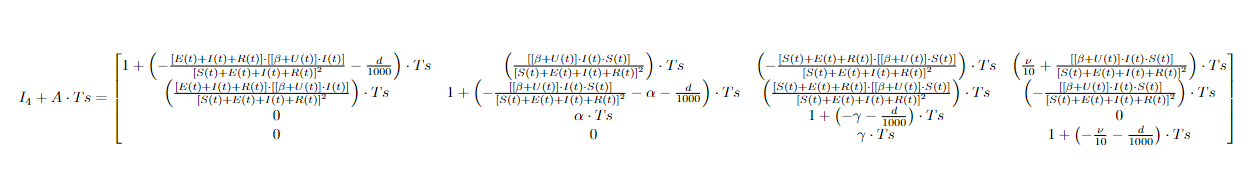

### 3.4 Analisis de Observabilidad


x_act=[0.1431
    0.0092
    0.0092
    0.8384 ];
U=0.5;
Ts=10;
k=1;
B = 0.3; %B +-0.2
d = 0.3; %d +-0.2
alpha = 0.09; %alpha_ +- 0.01
gamma = 0.104; %gamma_ +- 0.004
beta = 0.19; %beta_dos; +- 0.09
nu = 0.009; %nu_ +-0.001

C=[0 0 0 1];

Phi_S=...
    [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
    (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    0
    0];

Phi_E=...
    [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
    Ts*alpha
    0];

Phi_I=...
    [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    1+(-gamma-(d/1000))*Ts
    gamma*Ts];

Phi_R=...
    [((nu/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    0
    1+(-(nu/10)-(d/1000))*Ts];

Phi=[Phi_S Phi_E Phi_I Phi_R];


Mo=[C;C*Phi;C*Phi^2;C*Phi^3];

Numero_De_Condicion_Mo=cond(Mo)

Numero_De_Condicion_Mo = 116.8205

### 3.5 Generacion de datos

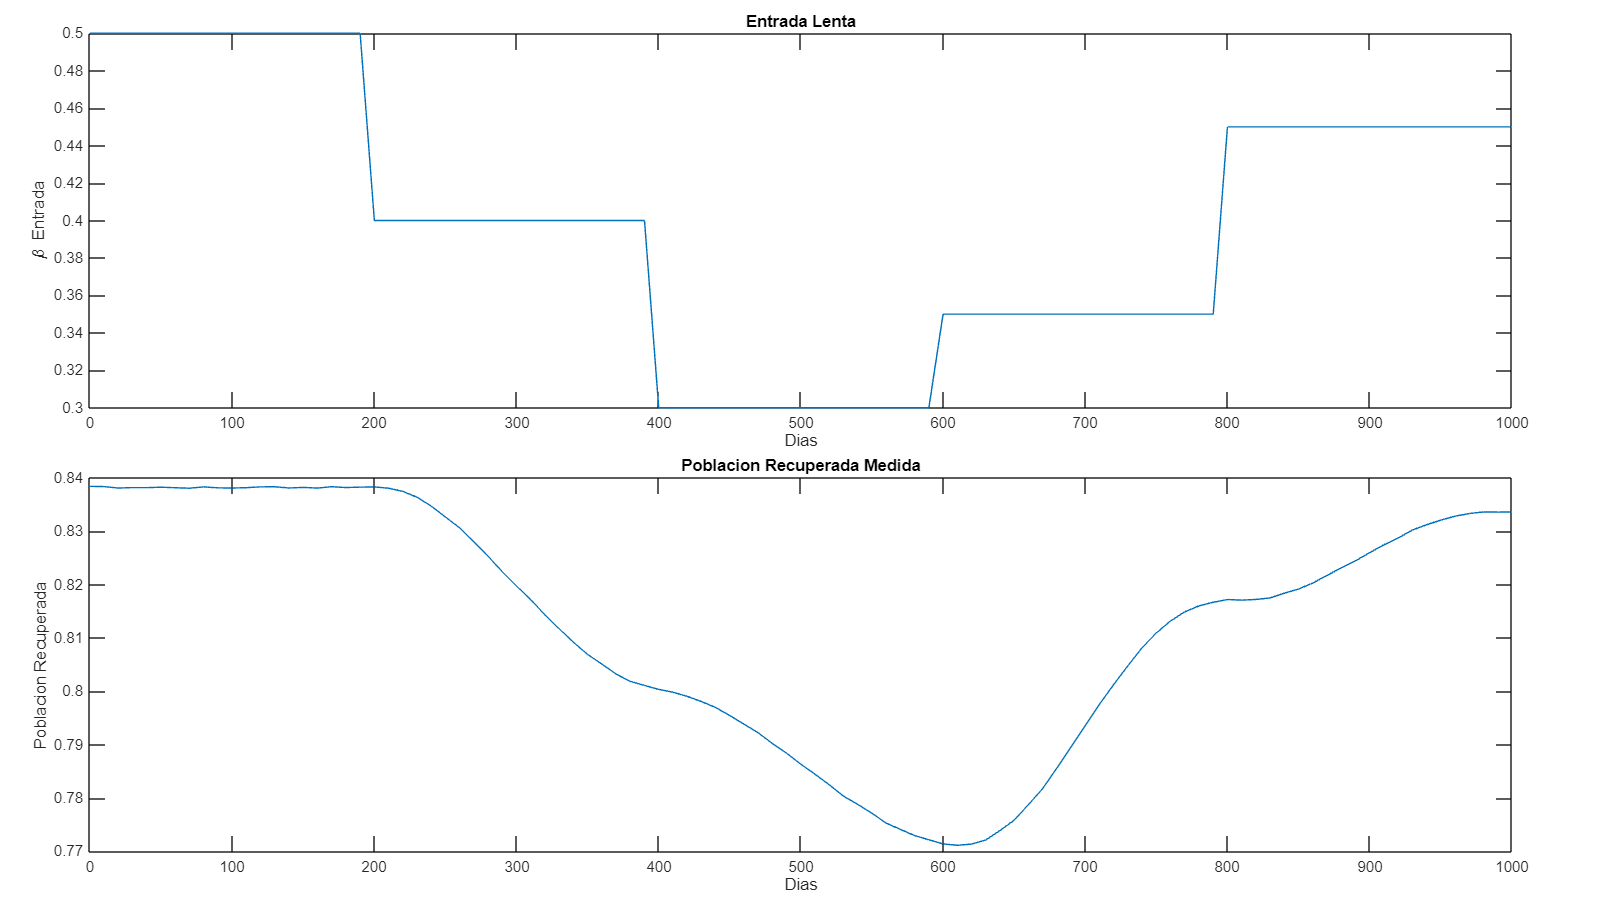

B=0.0001*1000; %B
d=0.0001*1000; %d
alpha=0.1; %alpha_
gamma=0.1; %gamma_
beta=0.2; %beta_dos;
nu=0.001*10; %nu_
mdl = 'SEIRS_2';
load_system(mdl)
path = [mdl, '/Modelo SEIRS'];
set_param(path, 'beta', num2str(beta));
set_param(path, 'gamma', num2str(gamma));
set_param(path, 'alpha', num2str(alpha));
set_param(path, 'nu', num2str(nu/10));
set_param(path, 'B', num2str(B/1000));
set_param(path, 'd', num2str(d/1000));
set_param(path, 'Ruido',1);
set_param(path,'Var_ruido',num2str(1e-8));
%punto de operacion u=0.5
S0=0.1431;
E0=0.0092;
I0=0.0092;
R0=0.8384;
TS=10;
Dias = 1000; % Tiempo máximo de la simulación
Ts = 10; % Período de muestreo definido anteriormente
t = (0:Ts:Dias)'; % Instantes de simulación
N = length(t);
%U = timetable(seconds(t),[0.5*ones(1,(N-1)/5) 0.51*ones(1,(N-1)/5) 0.49*ones(1,(N-1)/5) 0.48*ones(1,(N-1)/5) 0.5*ones(1,(N-1)/5+1)]');
u = timetable(seconds(t),[0.5*ones(1,(N-1)/5) 0.4*ones(1,(N-1)/5) 0.3*ones(1,(N-1)/5) 0.35*ones(1,(N-1)/5) 0.45*ones(1,(N-1)/5+1)]');
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(2,1,"Padding","compact","TileSpacing","compact");
nexttile,plot(t,u.Var1),xlabel('Dias');ylabel('\beta Entrada');title('Entrada Lenta')
nexttile, plot(t,sim_datos_exp.R.signals.values),xlabel('Dias');ylabel('Poblacion Recuperada');title('Poblacion Recuperada Medida')

dir_modelo = "SEIRS_2.slx";
sim_datos_exp=sim(dir_modelo);

Unable to find system or file 'SEIRS_2.slx'.


x_teo=[sim_datos_exp.S.signals.values'
    sim_datos_exp.E.signals.values'
    sim_datos_exp.I.signals.values'
    sim_datos_exp.R.signals.values'
    zeros(1,101)];
y=[ sim_datos_exp.R.signals.values];

### 3.6 Filtro de Kalman

#### 3.6.1.Inicializacion Filtro

B = 0.3; %B +-0.2
d = 0.3; %d +-0.2
alpha = 0.09; %alpha_ +- 0.01
gamma = 0.104; %gamma_ +- 0.004
beta = 0.19; %beta_dos; +- 0.09
nu = 0.009; %nu_ +-0.001

x0 = [S0 E0 I0 R0]';
n = length(x0);

P0 = 1e-4*eye(n);
P0(2,2)=1e-4;
P0(3,3)=1e-6;
P0(4,4)=1e-6;
Q=eye(n)*1e-4;
Q(2,2)=1e-5;
Q(3,3)=1e-6;
Q(4,4)=1e-6;


R_k = 1e-9;

x_act = zeros(n,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1);
de_x = zeros(n,N);
N_cond = zeros(N,1);
x_pre = x0;
P_pre = P0;
U=u.Var1;

#### 3.6.2.Filtro de Kalman

for k=1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R_k);
    x_act(:,k) = x_pre + K*(y(k) - C*x_pre);
    P_act = (eye(n)-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    % Actualización del estado para el siguiente paso (i+1)
    x_pre=...
        [x_act(1,k)+Ts*((B/1000)+(nu/10)*x_act(4,k)-((((beta+U(k))*x_act(3,k)*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k)))-(d/1000)*x_act(1,k))
        x_act(2,k)+Ts*(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))-alpha*x_act(2,k)-(d/1000)*x_act(2,k))
        x_act(3,k)+Ts*(alpha*x_act(2,k)-gamma*x_act(3,k)-(d/1000)*x_act(3,k))
        x_act(4,k)+Ts*(gamma*x_act(3,k)-(nu/10)*x_act(4,k)-(d/1000)*x_act(4,k))];


    Phi_S=...
        [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
        (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        0
        0];

    Phi_E=...
        [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
        Ts*alpha
        0];

    Phi_I=...
        [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        1+(-gamma-(d/1000))*Ts
        gamma*Ts];

    Phi_R=...
        [((nu/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        0
        1+(-(nu/10)-(d/1000))*Ts];

    Phi=[Phi_S Phi_E Phi_I Phi_R];
    P_pre = Phi*P_act*Phi' + Q;
    % Vectores con información
    N_cond(k) = cond(obsv(Phi,C));
    P_act_traza(k) = trace(P_act);
    K_norma(k) = norm(K);
    de_x(:,k) = sqrt(diag(P_act));
end

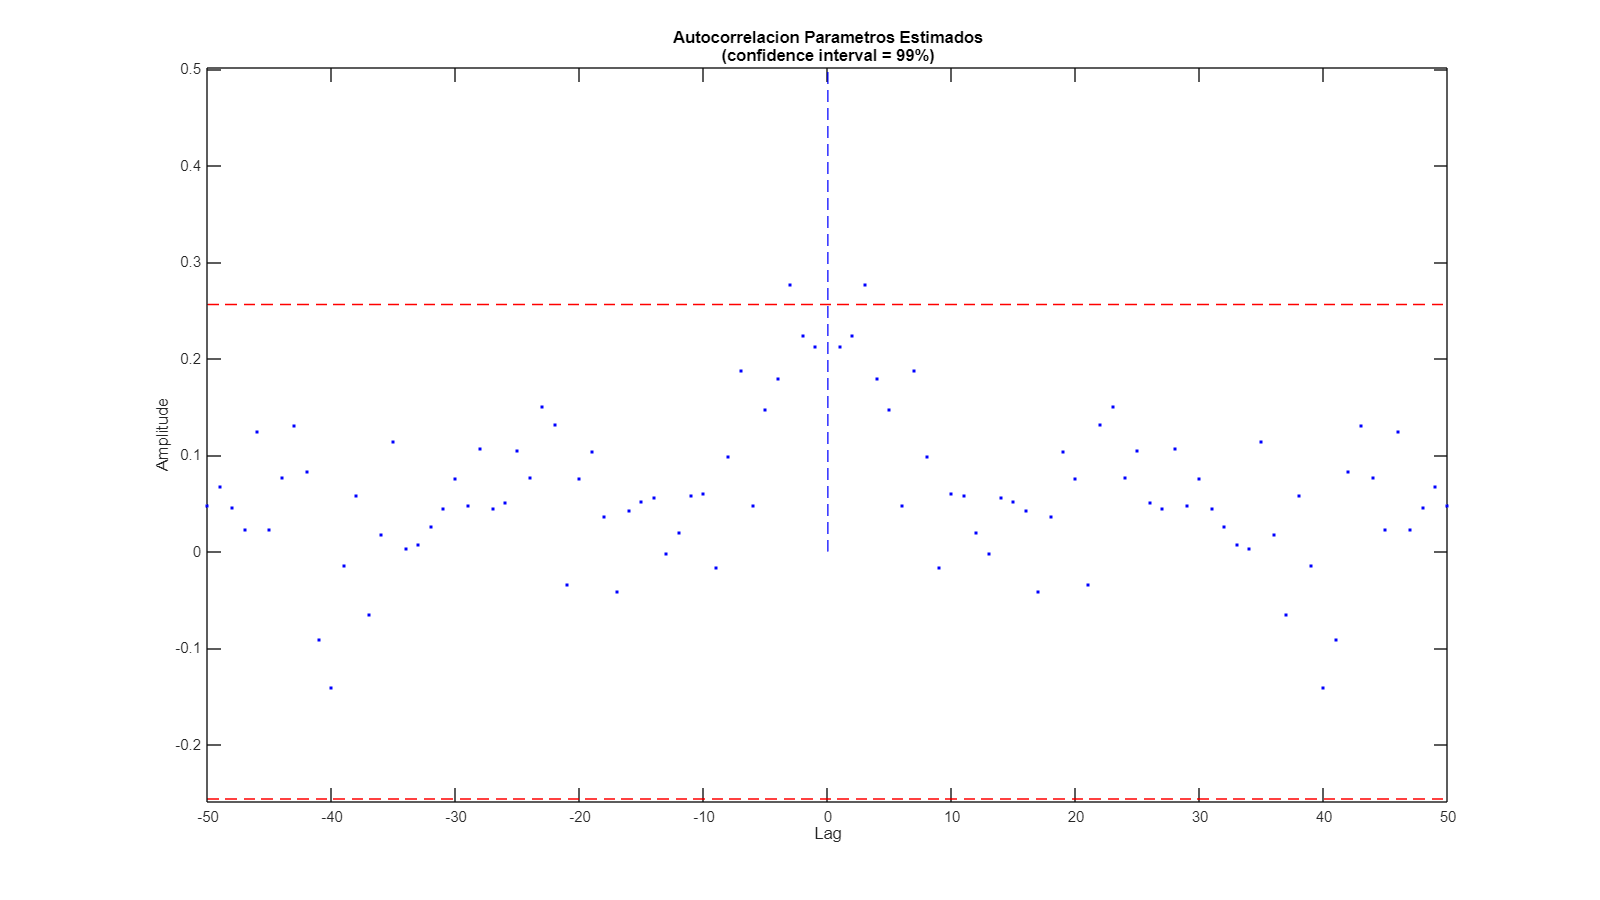

e_est = y - (C*x_act)';
figure

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);

lagmax = 50;
[R,lags,conf] = whiteness_test(e_est,lagmax,10);
plot(lags,R,'b.')
line([lags(1) lags(end)],conf*[1 1],'color','red','linestyle','--','linewidth',1)
line([lags(1) lags(end)],-conf*[1 1],'color','red','linestyle','--','linewidth',1)
line([0 0],[0 max(R)],'color','blue','linestyle','--','linewidth',0.1)
xlabel('Lag')
ylabel('Amplitude')
title({'Autocorrelacion Parametros Estimados';'(confidence interval = 99%)'})
ylim([ min([R,-conf])-0.002    max([R(1:ceil(lagmax)),conf,0.5])+0.002 ])

#### 3.6.3.Grafica de resultados 1

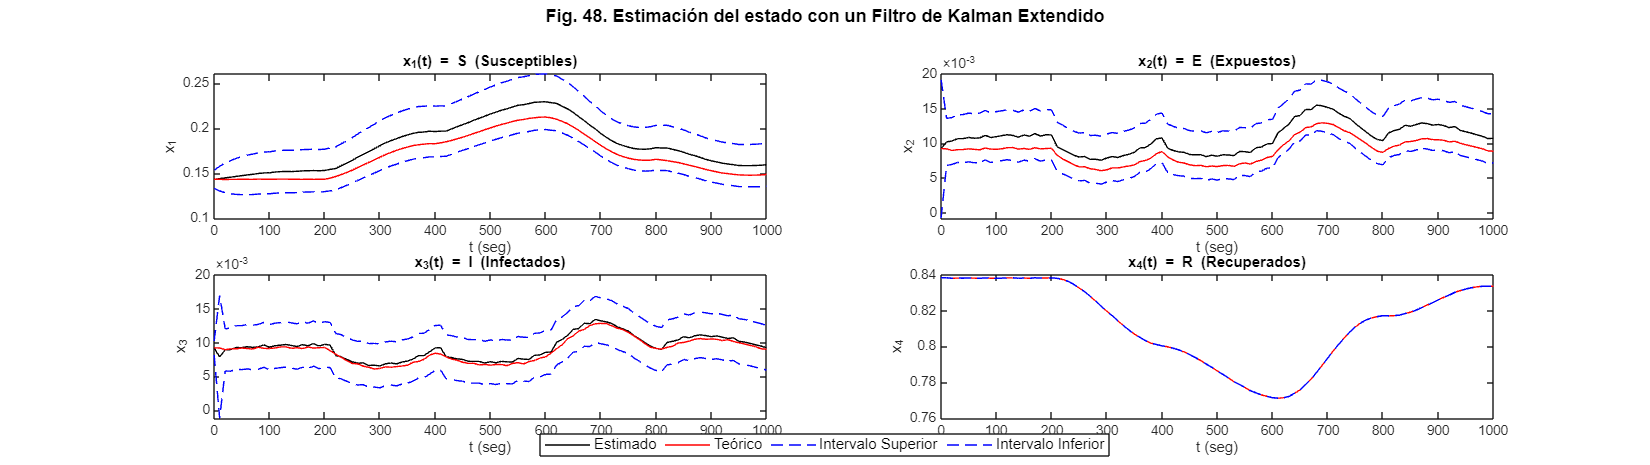

figure('Units','normalized','Position',[0 0 1 0.5])
sgtitle({'Fig. 48. Estimación del estado con un Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')
x_names = {'S (Susceptibles)', 'E (Expuestos)', 'I (Infectados)', 'R (Recuperados)'};

for k = 1:4
    subplot(2,2,k) % Ajuste para cuatro variables en un arreglo de 2x2
    plot(t, x_act(k,:)','k', ...                     % Estado estimado
        t, x_teo(k,:),'r', ...                     % Estado teórico
        t, (x_act(k,:) + de_x(k,:))','b--', ...    % Intervalo superior
        t, (x_act(k,:) - de_x(k,:))','b--')        % Intervalo inferior
    xlabel('t (seg)')
    ylabel(['x_' num2str(k)])
    title(['x_' num2str(k) '(t) = ' x_names{k}])
   
end
% Agregar una leyenda global
hL = legend({'Estimado', 'Teórico', 'Intervalo Superior', 'Intervalo Inferior'}, ...
    'Orientation', 'horizontal', 'FontSize', 10, 'Location', 'southoutside');
hL.Position = [0.4, 0.02, 0.2, 0.05]; % Ajustar la posición manualmente

#### 3.6.4.Grafica de resultados 2

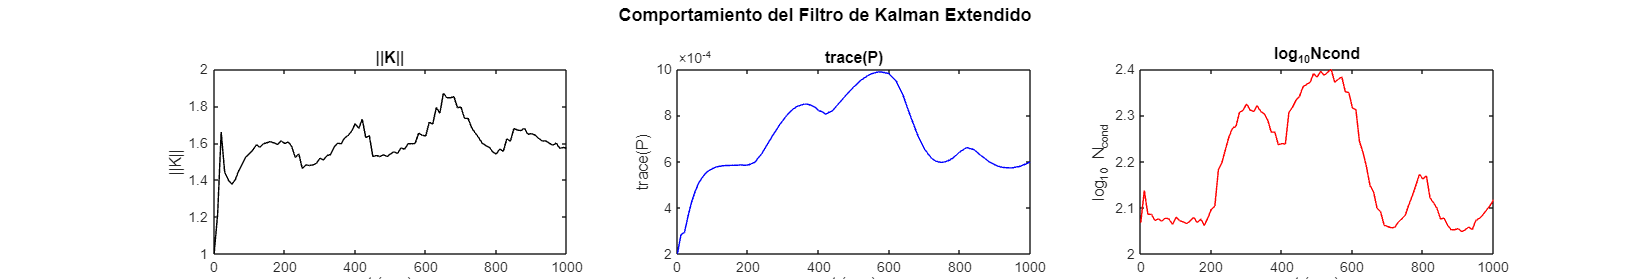

figure('Units','normalized','Position',[0 0 1 0.3])
sgtitle({'Comportamiento del Filtro de Kalman Extendido';''},'FontSize',12,'FontWeight','bold')

subplot(1,3,1)
plot(t, K_norma, 'k')
xlabel('t (seg)'), ylabel('||K||')
title('||K||')

subplot(1,3,2)
plot(t, P_act_traza, 'b')
xlabel('t (seg)'), ylabel('trace(P)')
title('trace(P)')

subplot(1,3,3)
plot(t, log10(N_cond), 'r')
xlabel('t (seg)'), ylabel('log_{10} N_{cond}')
title('log_{10}Ncond')

### 3.7 Modelo SEIR Discreto Para La Estimacion De $\nu$

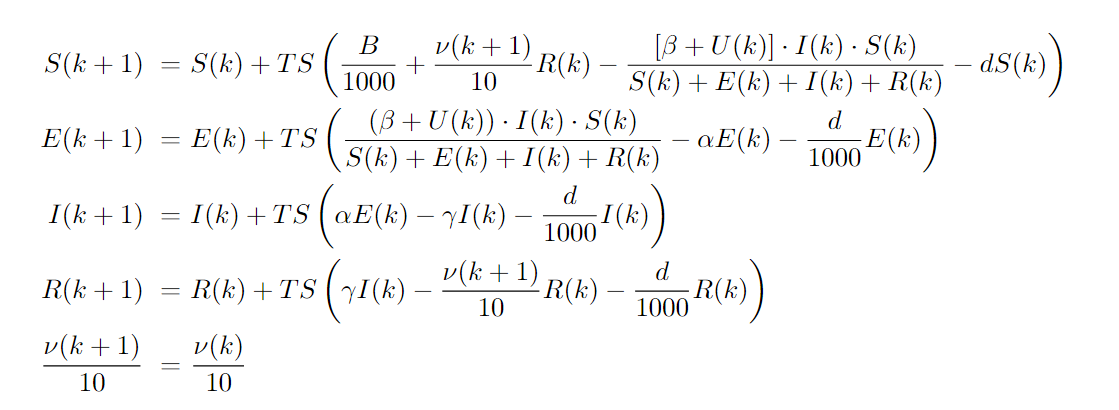

### 3.6 Matriz $\Phi$ Para La Estimacion De $\nu$

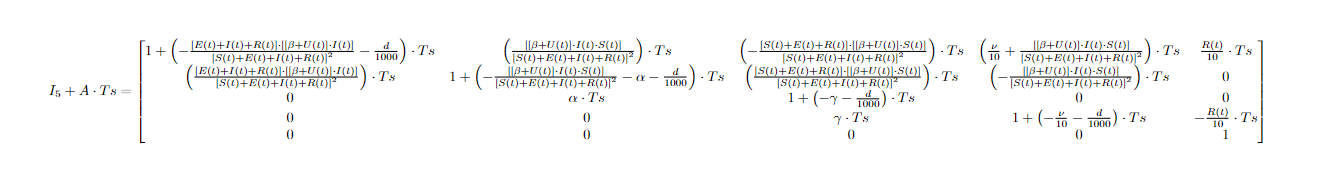

### 3.8 Analisis de Obsevabilidad

x_act=[0.1431 %S
    0.0092    %E
    0.0092    %I
    0.8384    %R
    0.01% 0.00862168642730242 %nu
    ];

U=0.5;
Ts=10;
k=1;
B = 0.334347777716906; %B
d = 0.342692168641646; %d
alpha = 0.0904963402600036; %alpha_
gamma = 0.104149917959794; %gamma_
beta = 0.189760832657602; %beta_dos;

C=[0 0 0 1 0];

Phi_S_Param=...
    [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
    (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    0
    0
    0];

Phi_E_Param=...
    [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
    1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
    Ts*alpha
    0
    0];

Phi_I_Param=...
    [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    1+(-gamma-(d/1000))*Ts
    gamma*Ts
    0];

Phi_R_Param=...
    [((x_act(5,k)/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
    0
    1+(-(x_act(5,k)/10)-(d/1000))*Ts
    0];

Phi_Nu_Param=...
    [(x_act(4,k)/10)*Ts
    0
    0
    -(x_act(4,k)/10)*Ts
    1];

Phi=[Phi_S_Param Phi_E_Param Phi_I_Param Phi_R_Param Phi_Nu_Param];


Mo=[C;C*Phi;C*Phi^2;C*Phi^3;C*Phi^4];
Numero_De_Condicion_Mo=cond(Mo)

Numero_De_Condicion_Mo = 6.8772e+04

### 3.9 Filtro de Kalman Conjunto

#### 3.9.1 Inicializacion del filtro

Nu0=0.013;
x0 = [S0 E0 I0 R0 Nu0]';
n = length(x0);
P0 = 1e-6*eye(n);
P0(2,2)=1e-4;
P0(3,3)=1e-6;
P0(4,4)=1e-6;
P0(5,5)=1e-3;
Q=eye(n)*1e-4;
Q(2,2)=1e-5;
Q(3,3)=1e-6;
Q(4,4)=1e-6;
Q(5,5)=1e-6;
R_k = 1e-9;

x_act = zeros(n,N);
P_act_traza = zeros(N,1);
K_norma = zeros(N,1);
de_x = zeros(n,N);
N_cond = zeros(N,1);
x_pre = x0;
P_pre = P0;

x_teo(5,:)=ones(1,101)*nu;

U=u.Var1;

#### 3.9.2 Filtro de Kalman Conjunto

for k=1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R_k);
    x_act(:,k) = x_pre + K*(y(k) - C*x_pre);
    P_act = (eye(n)-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    % Actualización del estado para el siguiente paso (i+1)
    x_pre=...
        [x_act(1,k)+Ts*((B/1000)+(x_act(5,k)/10)*x_act(4,k)-((((beta+U(k))*x_act(3,k)*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k)))-(d/1000)*x_act(1,k))
        x_act(2,k)+Ts*(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))-alpha*x_act(2,k)-(d/1000)*x_act(2,k))
        x_act(3,k)+Ts*(alpha*x_act(2,k)-gamma*x_act(3,k)-(d/1000)*x_act(3,k))
        x_act(4,k)+Ts*(gamma*x_act(3,k)-(x_act(5,k)/10)*x_act(4,k)-(d/1000)*x_act(4,k))
        x_act(5,k)];


    Phi_S_Param=...
        [1+(-(((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-(d/1000))*Ts
        (((x_act(2,k)+x_act(3,k)+x_act(4,k))*(( beta+U(k))*x_act(3,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        0
        0
        0];

    Phi_E_Param=...
        [(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)*Ts
        1 + (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2)-alpha-(d/1000))*Ts
        Ts*alpha
        0
        0];

    Phi_I_Param=...
        [(-(((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        ((((x_act(1,k)+x_act(2,k)+x_act(4,k))*((beta+U(k))*x_act(1,k)))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        1+(-gamma-(d/1000))*Ts
        gamma*Ts
        0];

    Phi_R_Param=...
        [((x_act(5,k)/10)+(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        (-(((beta+U(k))*x_act(3,k)*x_act(1,k))/(x_act(1,k)+x_act(2,k)+x_act(3,k)+x_act(4,k))^2))*Ts
        0
        1+(-(x_act(5,k)/10)-(d/1000))*Ts
        0];

    Phi_Nu_Param=...
        [(x_act(4,k)/10)*Ts
        0
        0
        -(x_act(4,k)/10)*Ts
        1];

    Phi=[Phi_S_Param Phi_E_Param Phi_I_Param Phi_R_Param Phi_Nu_Param];
    P_pre = Phi*P_act*Phi' + Q;
    % Vectores con información
    N_cond(k) = cond(obsv(Phi,C));
    P_act_traza(k) = trace(P_act);
    K_norma(k) = norm(K);
    de_x(:,k) = sqrt(diag(P_act));
end

#### 3.9.3 Grafica de resultados 1

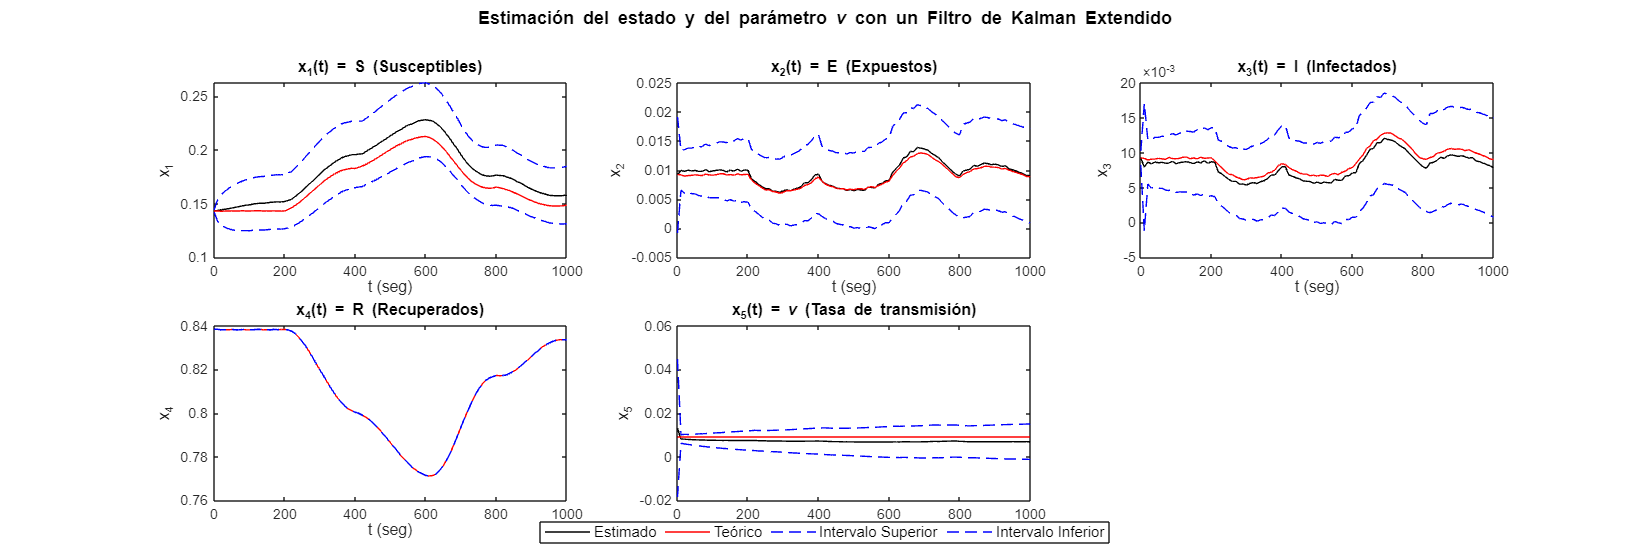

% Figura para las estimaciones de los estados y el parámetro \nu
figure('Units', 'normalized', 'Position', [0 0 1 0.6])
sgtitle({'Estimación del estado y del parámetro \nu con un Filtro de Kalman Extendido'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

% Nombres de las variables
x_names = {'S (Susceptibles)', 'E (Expuestos)', 'I (Infectados)', 'R (Recuperados)', '\nu (Tasa de transmisión)'};

% Crear los subgráficos
for k = 1:5
    subplot(2, 3, k) % Ajuste para cinco variables en un arreglo de 2x3
    plot(t, x_act(k, :)', 'k', ...                  % Estado estimado
        t, x_teo(k, :), 'r', ...                  % Estado teórico
        t, (x_act(k, :) + de_x(k, :))', 'b--', ... % Intervalo superior
        t, (x_act(k, :) - de_x(k, :))', 'b--')     % Intervalo inferior
    xlabel('t (seg)')
    ylabel(['x_' num2str(k)])
    title(['x_' num2str(k) '(t) = ' x_names{k}])
end

% Agregar una leyenda global
hL = legend({'Estimado', 'Teórico', 'Intervalo Superior', 'Intervalo Inferior'}, ...
    'Orientation', 'horizontal', 'FontSize', 10, 'Location', 'southoutside');
hL.Position = [0.4, 0.02, 0.2, 0.05]; % Ajustar la posición manualmente

#### 3.9.3 Grafica de Resultados 2 

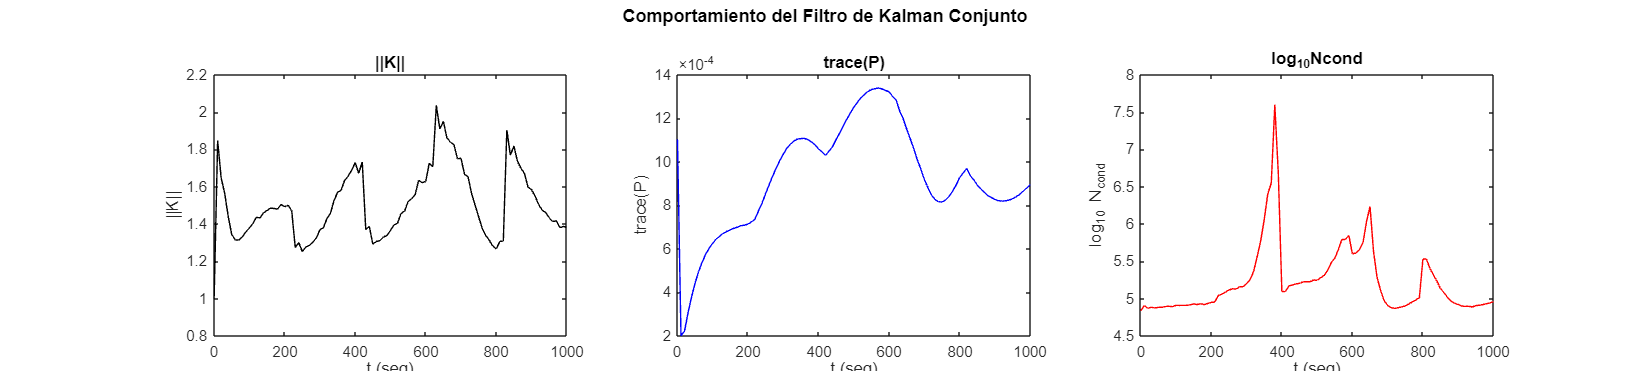

% Figura para el comportamiento del filtro de Kalman
figure('Units', 'normalized', 'Position', [0 0 1 0.4])
sgtitle({'Comportamiento del Filtro de Kalman Conjunto'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

subplot(1, 3, 1)
plot(t, K_norma, 'k')
xlabel('t (seg)'), ylabel('||K||')
title('||K||')

subplot(1, 3, 2)
plot(t, P_act_traza, 'b')
xlabel('t (seg)'), ylabel('trace(P)')
title('trace(P)')

subplot(1, 3, 3)
plot(t, log10(N_cond), 'r')
xlabel('t (seg)'), ylabel('log_{10} N_{cond}')
title('log_{10}Ncond')

### 3.10  Control De Realimentación Del Estado Con Un Filtro Extendido De Kalman

#### 3.10.1 Analisis de Controlabilidad

[A,B,C,D] = linmod('SEIRS_2_Linealizacion',[S0 E0 I0 R0],0.5);
Sc = ss(A,B,C,D);
Ts = 10;
Sd = c2d(Sc,Ts);

% Matriz Phi y cálculo de los polos
Phi_control = Sd.A;
Polos = eig(Phi_control)

Polos =    0.9990 + 0.0000i
   0.9555 + 0.1721i
   0.9555 - 0.1721i
   0.1329 + 0.0000i


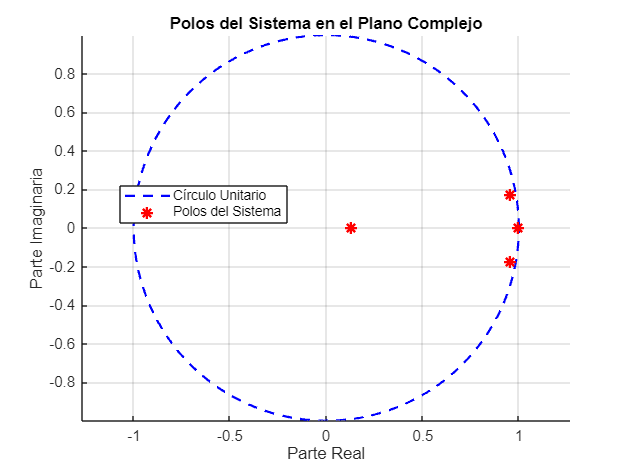


% Graficar el círculo unitario
theta = linspace(0, 2*pi, 1000);  % Angulo para el círculo
x_circle = cos(theta);            % Coordenadas x del círculo
y_circle = sin(theta);            % Coordenadas y del círculo

figure;
hold on;
plot(x_circle, y_circle, 'b--', 'LineWidth', 1.5); % Círculo unitario
plot(real(Polos), imag(Polos), 'r*', 'MarkerSize', 8, 'LineWidth', 1.5); % Polos
grid on;
axis equal;

% Etiquetas y título
title('Polos del Sistema en el Plano Complejo');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
legend('Círculo Unitario', 'Polos del Sistema', 'Location', 'Best');

hold off;

C_Control=[0 0 0 1]

C_Control =      0     0     0     1


Phi_control=Sd.A;
Gamma_control=Sd.B;
Polos=eig(Phi_control);
MC=ctrb(Phi_control,Gamma_control);
Rango_Mc=rank(MC);
Num_Mc=cond(MC);
K_control=place(Phi_control,Gamma_control,[Polos(1)-0.05 Polos(2)-0.05 Polos(3)-0.05 Polos(4)-0.05]);

u_0=0.5

u_0 = 0.5000

x0 = [S0 E0 I0 R0]';
n = length(x0);
P0 = 1e-6*eye(n);
Q=eye(n)*1e-6;
R_k = 1e-9;
pert=0;
sim("SEIRS_2_Control_Filtro.slx")

Derivative of state '1' in block 'SEIRS_2_Control_Filtro/Modelo SEIRS/S' at time 2.9008658303329455E-9 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)

### 4. Resultados

### 5. Referencias

- [1]       K. Rock, S. Brand, J. Moir, and M. J. Keeling, ‘Dynamics of infectious diseases’, Reports on Progress in Physics, vol. 77, no. 2, p. 026602, Jan. 2014.

- [2]  O. N. Bjørnstad, K. Shea, M. Krzywinski, and N. Altman, ‘The SEIRS model for infectious disease dynamics’, Nature Methods, vol. 17, no. 6, pp. 557–558, Jun. 2020.

- [3]  T. Tomé and M. de Oliveira, ‘Susceptible-infected-recovered and susceptible-exposed-infected models’, J. Phys. J. Phys. A: Math. Theor, vol. 16750, 03 2011.

- [4]        Bill & Melinda Gates Foundation. “SEIR and SEIRS Models — HIV Model Documentation.” *Docs.idmod.org*, docs.idmod.org/projects/emod-hiv/en/latest/model-seir.html. Accessed 14 Apr. 2024.

- [5]       Velez, C. M. (2024). Global sensitivity and uncertainty analysis (GSUA) (https://www.mathworks.com/matlabcentral/fileexchange/47758-global-sensitivity-and-uncertainty-analysis-gsua), MATLAB Central File Exchange.

- [6]       Saltelli, A., et al (2010).  Variance based sensitivity analysis of model output. Design and estimator for the total sensitivity index. Computer Physics Communications, 181(2), 259-270.